# Furuta Pendulum - Submission Notes and Explicit Nominal Test

## 1. Scope and Files

This supplement adds the short explanations needed for the Week 6 and Week 9 submission. The six existing teaching files and the accepted gains remain unchanged. Use this file for explicit, repeatable nominal tests of all three controllers.

assert(isfolder('data') && isfolder('models'),'Set Current Folder to Furuta_Clean_Project.');
addpath('models','geometry');
load('data/Linear_Model_Data.mat');
load('data/Accepted_Controller_Data.mat');
xe=x_equilibrium;taue=tau_equilibrium;
load('data/Physical_Parameters.mat');


## 2. Modelling Assumptions

Assume rigid bodies, ideal revolute joints and viscous joint damping. The input is output-joint torque in N m, not voltage or PWM. The model does not include motor electrical dynamics, gearbox backlash, Coulomb friction, sensor noise or sample delay. All four joint states are available in simulation. The analytical model uses the same CAD geometry, masses and inertia tensors as Simscape. These assumptions define the simulation scope; they do not establish hardware accuracy.

assumptions=table(["Rigid bodies and ideal joints";"Viscous damping"; ...
    "Direct arm-joint torque input";"Four ideal measured states"; ...
    "Motor electrical dynamics";"Backlash, sensor noise and sampling"], ...
    ["Included assumption";"Included";"Included assumption";"Included assumption"; ...
    "Not modelled";"Not modelled"], ...
    'VariableNames',{'Item','Treatment'})

assumptions = 6×2 table
                    Item                           Treatment      
    _____________________________________    _____________________

    "Rigid bodies and ideal joints"          "Included assumption"
    "Viscous damping"                        "Included"           
    "Direct arm-joint torque input"          "Included assumption"
    "Four ideal measured states"             "Included assumption"
    "Motor electrical dynamics"              "Not modelled"       
    "Backlash, sensor noise and sampling"    "Not modelled"       


## 3. Physical Parameters and Sources

Masses, COM vectors, inertia tensors and frame transforms were extracted from the saved CAD/Simscape model and converted to SI units. Damping values come from the saved joint settings; no hardware friction-identification experiment is claimed. The arm-axis inertia below excludes the pendulum and reflected motor inertia. The COM distance is not the full pendulum length.

arm_pivot_radius=norm(d_pivot(1:2));
pendulum_COM_distance=norm(c_pend);
arm_axis_inertia=I_arm(3,3)+m_arm*sum(c_arm(1:2).^2);
pendulum_axis_inertia=I_pend(3,3)+m_pend*sum(c_pend(1:2).^2);
Parameter=["Arm mass";"Pendulum mass";"Pivot radial distance"; ...
    "Pendulum pivot-to-COM distance";"Arm group motor-axis inertia"; ...
    "Pendulum pivot-axis inertia";"Arm damping";"Pendulum damping"];
Value=[m_arm;m_pend;arm_pivot_radius;pendulum_COM_distance; ...
    arm_axis_inertia;pendulum_axis_inertia;D_mech(1,1);D_mech(2,2)];
Unit=["kg";"kg";"m";"m";"kg m^2";"kg m^2";"N m s/rad";"N m s/rad"];
Source=[repmat("Saved CAD/Simscape model, SI conversion",6,1); ...
    repmat("Saved joint damping setting; not measured friction",2,1)];
parameter_table=table(Parameter,Value,Unit,Source)

parameter_table = 8×4 table
               Parameter                  Value          Unit                               Source                       
    ________________________________    __________    ___________    ____________________________________________________

    "Arm mass"                             0.18332    "kg"           "Saved CAD/Simscape model, SI conversion"           
    "Pendulum mass"                      0.0072213    "kg"           "Saved CAD/Simscape model, SI conversion"           
    "Pivot radial distance"                  0.033    "m"            "Saved CAD/Simscape model, SI conversion"           
    "Pendulum pivot-to-COM distance"      0.023551    "m"            "Saved CAD/Simscape model, SI conversion"           
    "Arm group motor-axis inertia"      0.00014238    "kg m^2"       "Saved CAD/Simscape model, SI conv

c_arm

c_arm =    -0.0005
    0.0005
    0.0264


c_pend

c_pend =    -0.0182
    0.0128
    0.0076


I_arm

I_arm = 1.0e-03 *

    0.1513   -0.0004    0.0006
   -0.0004    0.1512   -0.0006
    0.0006   -0.0006    0.1423


I_pend

I_pend = 1.0e-05 *

    0.3557    0.3700    0.1362
    0.3700    0.6216   -0.0958
    0.1362   -0.0958    0.7982


## 4. PID Design Justification

The pendulum PD terms provide fast balance action. Arm P and D return the arm and shape its motion; the arm integral term reduces persistent arm-position error. The arm signs follow the CAD coordinates, so conventional error-form arm PID gains are negative. Historical tuning screened 720 gain combinations, followed by nonlinear trials and integral-gain trials. This is earlier tuning evidence, not a new 720-point run. The simplified PID keeps bounded active integration but removes inactive tracking. Select the controller before each run.

signed_PID_gains=table([-PID.ArmP;-PID.ArmI;-PID.ArmD;PID.PendP;PID.PendD], ...
    'RowNames',{'Arm Kp','Arm Ki','Arm Kd','Pendulum Kp','Pendulum Kd'}, ...
    'VariableNames',{'Gain'})

signed_PID_gains = 5×1 table
                      Gain   
                   __________

    Arm Kp         -0.0018402
    Arm Ki            -0.0007
    Arm Kd         -0.0028351
    Pendulum Kp       0.10464
    Pendulum Kd     0.0097256


L=[PID.ArmP,-PID.PendP,PID.ArmD,-PID.PendD];
PID_poles=eig([A+B*L,B;PID.ArmI,0,0,0,0])

PID_poles =  -24.9194 + 0.0000i
  -4.0253 + 7.4173i
  -4.0253 - 7.4173i
  -0.4421 + 0.4057i
  -0.4421 - 0.4057i


## 5. Pole-Placement Design Justification

The nominal targets are pendulum peak <=8 deg, pendulum settling <=2.5 s and arm settling <=8 s. Earlier tuning compared nine pole sets and used nonlinear recovery and torque headroom to choose [-5 -6 -8 -10]. These real poles give a faster linear decay than the original set, while the nonlinear tests determine actual recovery. The 2-percent modal estimate is only a guide. This historical table shows the tradeoff: lower excursion and RMS torque, but higher peak torque.

desired_poles=[-5,-6,-8,-10];
Kpp=place(A,B,desired_poles);
PP_poles=eig(A-B*Kpp)

PP_poles =   -10.0000
   -8.0000
   -6.0000
   -5.0000


modal_settling_estimate=4/min(abs(real(desired_poles)))

modal_settling_estimate = 0.8000

historical_PP_comparison=table(["Original poles";"Accepted poles"], ...
    [5.4206;3.0541],[2.725;1.307],[99.8717;18.4271], ...
    [0.0059633;0.0088045],[0.0009410;0.0006979], ...
    'VariableNames',{'HistoricalDesign','PendulumPeak_deg','PendulumSettling_s', ...
    'ArmPeak_deg','PeakTorque_Nm','RmsTorque_Nm'})

historical_PP_comparison = 2×6 table
    HistoricalDesign    PendulumPeak_deg    PendulumSettling_s    ArmPeak_deg    PeakTorque_Nm    RmsTorque_Nm
    ________________    ________________    __________________    ___________    _____________    ____________

    "Original poles"         5.4206               2.725             99.872         0.0059633        0.000941  
    "Accepted poles"         3.0541               1.307             18.427         0.0088045       0.0006979  


## 6. LQR Weight Justification

Use state-reference scales of 90 deg, 5 deg, 2 rad/s and 4 rad/s, and a torque scale of 0.01 N m. These scales normalize different units; they are not hard state limits. The accepted Q multiplies the inverse squared scales by [0.2,0.1,0,0.1]. R is the inverse squared torque scale. Earlier tuning screened 480 Q choices and tested seven distinct gains on the nonlinear plant. The accepted design balanced pendulum error and control effort after the earlier recovery gate. A zero arm-velocity weight is allowed here because the resulting design is stabilizing. Plain LQR has no integral action.

state_scales=[deg2rad(90);deg2rad(5);2;4];
torque_scale=0.01;
weight_multipliers=diag(Q).*state_scales.^2

weight_multipliers =     0.2000
    0.1000
         0
    0.1000


Q_from_scales=diag(weight_multipliers./state_scales.^2)

Q_from_scales =     0.0811         0         0         0
         0   13.1312         0         0
         0         0         0         0
         0         0         0    0.0063


R_from_scale=1/torque_scale^2

R_from_scale = 10000

assert(norm(Q-Q_from_scales,'fro')<1e-10 && abs(Rcost-R_from_scale)<1e-10);
[Klqr,P]=lqr(A,B,Q,Rcost);
LQR_poles=eig(A-B*Klqr)

LQR_poles =  -13.8813 + 5.9457i
 -13.8813 - 5.9457i
  -2.7031 + 2.0226i
  -2.7031 - 2.0226i


assert(norm(Kpp-K_pp)<1e-7 && norm(Klqr-K_lqr)<1e-7);


## 7. Explicit Nominal Test for Each Controller

The test structure below drives the actual SimulationInput settings and the saved metadata. For every controller, the local function explicitly sets both pulse edges, both amplitudes, the actuator limit, run time, equilibrium and controller gains. It uses a temporary copy of the saved plant, so an open model with unsaved edits is preserved. It does not change the six existing files or overwrite their earlier result files.

test=struct('pulse_Nm',0.01,'on_s',1,'off_s',1.05,'duration_s',10,'limit_Nm',0.01);
[nominal_summary,nominal_runs]=explicit_nominal_runs(A,B,xe,taue,PID,Kpp,Klqr,test);
nominal_summary

nominal_summary = 3×9 table
    PeakPendulum_deg    PeakArm_deg    PendulumSettling_s    ArmSettling_s    PeakTorque_Nm    RmsTorque_Nm    PendulumIAE_rad_s    SaturationFraction       Controller   
    ________________    ___________    __________________    _____________    _____________    ____________    _________________    __________________    ________________

         2.7646           16.123             0.934               6.907          0.0092042       0.00068544         0.015344                 0             "PID"           
         3.0541           18.427             1.307               1.338          0.0088045       0.00069794         0.017122                 0           

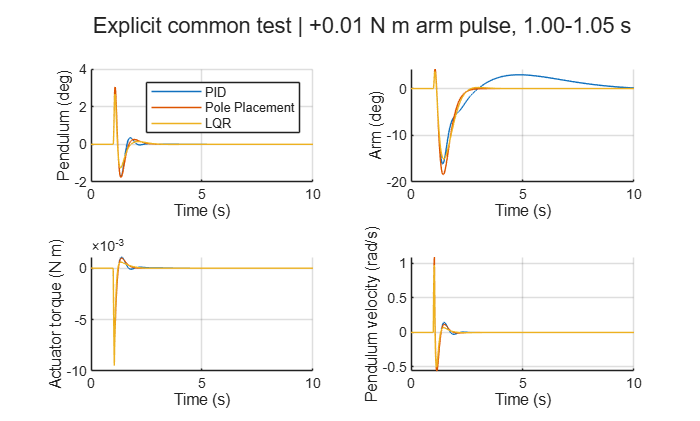

save('results/Explicit_Nominal_Test.mat','nominal_summary','nominal_runs','test');
writetable(nominal_summary,'results/Explicit_Nominal_Test.csv');
figure('Name','Explicit nominal test','Color','w');tiledlayout(2,2);
for k=1:3
    r=nominal_runs{k};
    nexttile(1);hold on;plot(r.t,rad2deg(r.x(:,2)));
    nexttile(2);hold on;plot(r.t,rad2deg(r.x(:,1)));
    nexttile(3);hold on;plot(r.t,r.u);
    nexttile(4);hold on;plot(r.t,r.x(:,4));
end
nexttile(1);grid on;xlabel('Time (s)');ylabel('Pendulum (deg)');legend('PID','Pole Placement','LQR');
nexttile(2);grid on;xlabel('Time (s)');ylabel('Arm (deg)');
nexttile(3);grid on;xlabel('Time (s)');ylabel('Actuator torque (N m)');
nexttile(4);grid on;xlabel('Time (s)');ylabel('Pendulum velocity (rad/s)');
sgtitle('Explicit common test | +0.01 N m arm pulse, 1.00-1.05 s');
drawnow;exportgraphics(gcf,'results/Explicit_Nominal_Test.png','Resolution',140);

## 8. Phase Boundaries and Review Limits

Week 6 requires a MATLAB model with open-loop dynamic validation. Week 9 requires stability analysis and PID, pole placement and LQR designs with simulation results and pole/eigenvalue justification. Swing-up, Stateflow, HIL, dashboard and the hardware-synchronized digital twin belong to the wider final project. Downward-equilibrium analysis is not swing-up. The phase wording does not require a separate Week 6/9 PDF unless the instructor adds that instruction. The full technical report is part of final submission. The evidence here applies to the saved model and the tested conditions, not every unsaved model edit or physical hardware. Stable linear poles prove local linear stability, not global saturated nonlinear stability.

phase_table=table(["Week 6";"Week 9";"Week 13 / final"], ...
    ["Model and open-loop validation"; ...
     "Stability, three controller designs and simulation evidence"; ...
     "Hardware/HIL, hybrid logic, dashboard/digital twin and full report"], ...
    'VariableNames',{'Phase','MainDeliverables'})

phase_table = 3×2 table
          Phase                                    MainDeliverables                          
    _________________    ____________________________________________________________________

    "Week 6"             "Model and open-loop validation"                                    
    "Week 9"             "Stability, three controller designs and simulation evidence"       
    "Week 13 / final"    "Hardware/HIL, hybrid logic, dashboard/digital twin and full report"


sources=["Project Description F26(6).pdf, Sections 4.1-4.3 and 8.1"; ...
    "Historical PID design narrative: Furuta_PID_Controller.m"; ...
    "Historical pole tuning: Pole_Placement_Tuning_Report.md"; ...
    "Historical LQR tuning: LQR_Controller_Notes.md and screen_lqr_design.m"]

sources = 4×1 string array
    "Project Description F26(6).pdf, Sections 4.1-4.3 and 8.1"
    "Historical PID design narrative: Furuta_PID_Controller.m"
    "Historical pole tuning: Pole_Placement_Tuning_Report.md"
    "Historical LQR tuning: LQR_Controller_Notes.md and screen_lqr_design.m"


save('results/Submission_Notes_Checked.mat','parameter_table','PID_poles','PP_poles','LQR_poles','phase_table');


## Local Functions

These functions stay inside this Live Script. They prepare temporary simulations and calculate the displayed metrics.

function [summary,runs] = explicit_nominal_runs(A,B,xe,taue,PID,Kpp,Klqr,test)
% Use a temporary copy of the saved plant. Preserve the open dirty model.
assert(~bdIsLoaded('Furuta_Explicit_Nominal'),'Close the earlier temporary nominal model first.');
folder=tempname;mkdir(folder);model='Furuta_Explicit_Nominal';
copyfile(fullfile(pwd,'models','Furuta_StudyF.slx'),fullfile(folder,[model '.slx']));
load_system(fullfile(folder,[model '.slx']));
cleanup=onCleanup(@()close_system(model,0));
names={'PID','Pole Placement','LQR'};runs=cell(3,1);summary=table;
for k=1:3
    in=Simulink.SimulationInput(model);
    in=in.setModelParameter('StopTime',num2str(test.duration_s,17));
    in=in.setBlockParameter([model '/Measured states'],'OpenAtSimulationStart','off');
    in=in.setBlockParameter([model '/Applied torque Nm'],'OpenAtSimulationStart','off');
    in=in.setBlockParameter([model '/Controller selector'],'controller_choice',names{k});
    in=in.setBlockParameter([model '/Pulse starts'],'Time',num2str(test.on_s,17));
    in=in.setBlockParameter([model '/Pulse starts'],'Before','0');
    in=in.setBlockParameter([model '/Pulse starts'],'After',num2str(test.pulse_Nm,17));
    in=in.setBlockParameter([model '/Pulse ends'],'Time',num2str(test.off_s,17));
    in=in.setBlockParameter([model '/Pulse ends'],'Before','0');
    in=in.setBlockParameter([model '/Pulse ends'],'After',num2str(-test.pulse_Nm,17));
    in=in.setVariable('tau_limit_sim',test.limit_Nm,'Workspace',model);
    in=in.setVariable('xe_controller',xe,'Workspace',model);
    in=in.setVariable('taue_controller',taue,'Workspace',model);
    if k==1
        fields={'ArmP','ArmI','ArmD','PendP','PendD'};
        for j=1:numel(fields)
            in=in.setVariable(['pid_' fields{j}],PID.(fields{j}),'Workspace',model);
        end
    elseif k==2
        in=in.setVariable('K_pp_controller',Kpp,'Workspace',model);
    else
        in=in.setVariable('K_lqr_controller',Klqr,'Workspace',model);
    end
    raw=sim(in);xs=raw.x_simscape;us=raw.tau_controller;
    t=(0:0.001:test.duration_s)';
    [tx,ix]=unique(xs.Time);[tu,iu]=unique(us.Time);
    x=interp1(tx,xs.Data(ix,:),t,'pchip')-xe';
    u=interp1(tu,us.Data(iu,:),t,'pchip');
    assert(all(isfinite(x(:))) && all(isfinite(u)),'Incomplete simulation result.');
    performance=response_metrics(t,x,u,test.off_s,test.limit_Nm);
    performance.Controller=string(names{k});summary=[summary;performance];
    runs{k}=struct('t',t,'x',x,'u',u,'performance',performance,'test',test,'A',A,'B',B);
end
end

function row=response_metrics(t,x,u,pulseEnd,limit)
row=table(max(abs(rad2deg(x(:,2)))),max(abs(rad2deg(x(:,1)))), ...
    settle(t,x(:,2),deg2rad(0.1),pulseEnd),settle(t,x(:,1),deg2rad(1),pulseEnd), ...
    max(abs(u)),sqrt(trapz(t,u.^2)/(t(end)-t(1))),trapz(t,abs(x(:,2))), ...
    trapz(t,double(abs(u)>=limit*(1-1e-6)))/(t(end)-t(1)), ...
    'VariableNames',{'PeakPendulum_deg','PeakArm_deg','PendulumSettling_s', ...
    'ArmSettling_s','PeakTorque_Nm','RmsTorque_Nm','PendulumIAE_rad_s','SaturationFraction'});
end

function value=settle(t,y,band,start)
outside=find(t>=start & abs(y)>band);
if isempty(outside),value=0;
elseif outside(end)==numel(t),value=Inf;
else,value=t(outside(end)+1)-start;
end
end
